# Conditional Variational Autoencoderを使った画像の生成

clc, clear, close;

## 画像の準備

Digitsデータセットを使用して、手書きの数字文字を学習します。

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');

imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

学習用と検証用とに分けます。

[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.8, 'randomized');
classes = unique(imdsTrain.Labels)

classes = 10×1 の categorical 配列
     0 
     1 
     2 
     3 
     4 
     5 
     6 
     7 
     8 
     9 


classNum = length(classes)

classNum = 10

numTrainImages = length(imdsTrain.Files)

numTrainImages = 8000

## ネットワークの構築

VAEと同じく、ネットワークはエンコーダ部分と、デコーダ部分に分かれます。VAEとの違いは、ラベル情報をエンコーダ、デコーダともに入力することです。入力の仕方としては、本例では、ラベル情報はOne-Hotベクトル化した後、下記のようにします。

エンコーダ部分：最後段の特徴マップを全結合層でベクトル化し、One-Hotベクトルを結合する。その後全結合層を経て潜在変数ベクトルとする。

デコーダ部分：潜在変数ベクトルに、One-Hotベクトルを結合する

latentDim = 20; % 潜在変数の次元数
imageSize = [28 28 1];

% エンコーダ（画像入力の部分）
encoderLG1 = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

% エンコーダ（ラベル入力の部分）
encoderLG2 = layerGraph([
   imageInputLayer([1 1 2*latentDim + classNum],"Normalization", 'none', "Name", 'input_label')
   fullyConnectedLayer(2*latentDim, 'Name', 'fc_encoder')]);

% デコーダ
decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim+classNum], "Normalization","none","Name",'input_decoder')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

学習の途中で潜在変数にランダムノイズを付加およびラベル情報を付加する必要があるため、カスタムの学習ループを定義します。

自動微分を使うため、エンコーダ、デコーダともにdlnetworkに変換します。

encoderNet1 = dlnetwork(encoderLG1);
encoderNet2 = dlnetwork(encoderLG2);
decoderNet = dlnetwork(decoderLG);

## 学習オプションの設定

VAEの場合と同様に設定していきます。

executionEnvironment = "auto";
numEpochs = 500;
minibatchSize = 500;
imdsTrain.ReadSize = minibatchSize;
lr = 1e-3;
numIterations = floor(numTrainImages/minibatchSize);
iteration = 0;

avgGradientsEncoder1 = [];
avgGradientsSquaredEncoder1 = [];
avgGradientsEncoder2 = [];
avgGradientsSquaredEncoder2 = [];
avgGradientsDecoder = [];
avgGradientsSquaredDecoder = [];

## 学習

カスタムのトレーニングループを使って学習させます。

ループの中では、下記の処理を逐次実行していきます。

- 学習データセット（ミニバッチデータ）の準備

- ミニバッチデータを `dlarray` オブジェクトに変換する

- （GPU環境があればさらに、dlarrayをgpuArrayオブジェクトに変換する）

- modelGradients関数およびdlfeval関数を使って、ネットワークの損失および勾配を計算する

- adamupdateを使ってネットワークを学習させる

Epoch : 1 Test ELBO loss = 24.9067. Time taken for epoch = 12.5169s


Epoch : 11 Test ELBO loss = 17.8109. Time taken for epoch = 15.2984s


Epoch : 21 Test ELBO loss = 16.1505. Time taken for epoch = 12.63s


Epoch : 31 Test ELBO loss = 15.9074. Time taken for epoch = 11.654s


Epoch : 41 Test ELBO loss = 15.5997. Time taken for epoch = 11.7249s


Epoch : 51 Test ELBO loss = 15.3017. Time taken for epoch = 14.464s


Epoch : 61 Test ELBO loss = 15.2308. Time taken for epoch = 14.0885s


Epoch : 71 Test ELBO loss = 15.1663. Time taken for epoch = 13.4797s


Epoch : 81 Test ELBO loss = 15.1937. Time taken for epoch = 13.8437s


Epoch : 91 Test ELBO loss = 15.0484. Time taken for epoch = 14.3673s


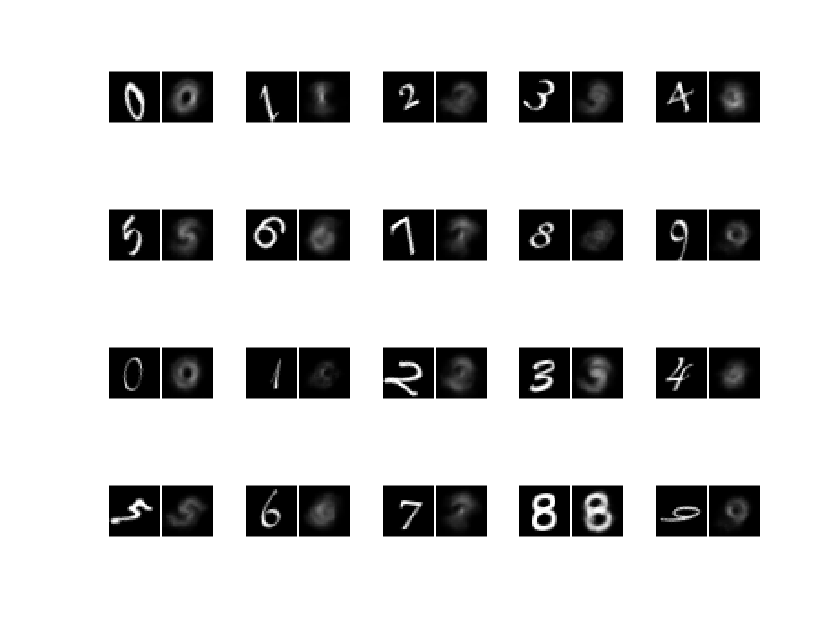

isTrain = true;
XTest = readall(imdsValidation);
XTest = dlarray(single(cat(4,XTest{:}))/255, 'SSCB');
YTest = full(ind2vec(double(imdsValidation.Labels)', classNum));
YTest = dlarray(single(reshape(YTest, [1,1,size(YTest)])), 'SSCB');

if isTrain
    for epoch=1:numEpochs
        tic;
        reset(imdsTrain);
        imdsTrain = shuffle(imdsTrain);
        for i=1:numIterations
            iteration = iteration + 1;
            idx = (i-1)*imdsTrain.ReadSize+1:i*imdsTrain.ReadSize;
            
            % ミニバッチの準備
            XBatch = read(imdsTrain);
            XBatch = dlarray(single(cat(4,XBatch{:}))/255, 'SSCB');
            YBatch = full(ind2vec(double(imdsTrain.Labels(idx))', classNum));
            YBatch = dlarray(single(reshape(YBatch, [1,1,size(YBatch)])), 'SSCB');
            
            if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
                XBatch = gpuArray(XBatch);           
            end 
                
            % 損失と勾配の計算
            [infGrad1, infGrad2, genGrad] = dlfeval(...
                @modelGradients, encoderNet1, encoderNet2, decoderNet, XBatch, YBatch);
            
            % 学習
            [decoderNet.Learnables, avgGradientsDecoder, avgGradientsSquaredDecoder] = ...
                adamupdate(decoderNet.Learnables, ...
                    genGrad, avgGradientsDecoder, avgGradientsSquaredDecoder, iteration, lr);
            [encoderNet1.Learnables, avgGradientsEncoder1, avgGradientsSquaredEncoder1] = ...
                adamupdate(encoderNet1.Learnables, ...
                    infGrad1, avgGradientsEncoder1, avgGradientsSquaredEncoder1, iteration, lr);
            [encoderNet2.Learnables, avgGradientsEncoder2, avgGradientsSquaredEncoder2] = ...
                adamupdate(encoderNet2.Learnables, ...
                    infGrad2, avgGradientsEncoder2, avgGradientsSquaredEncoder2, iteration, lr);
        end
        elapsedTime = toc;        
        
        if mod(epoch, 10) == 1 % 検証用データを使って損失を計算
            [z, zMean, zLogvar] = sampling(encoderNet1, encoderNet2, XTest, YTest);
            z = cat(3, z, YTest);
            xPred = sigmoid(forward(decoderNet, z));
            elbo = ELBOloss(XTest, xPred, zMean, zLogvar);
            disp("Epoch : "+epoch+" Test ELBO loss = "+gather(extractdata(elbo))+...
                ". Time taken for epoch = "+ elapsedTime + "s") 
        end

        % 50エポックごとに学習率を小さく
        if mod(epoch, 50) == 0
            lr = lr * 0.5;
        end
        % 現状の生成画像を確認
        visualizeReconstruction(XTest, imdsValidation.Labels, encoderNet1, encoderNet2, decoderNet);
        drawnow;
    end
    
    % 結果の保存
    save Nets encoderNet1 encoderNet2 decoderNet;
else
    load Nets.mat
end

## 学習結果の可視化

クラスごとに入力画像を再構成させてみます。

visualizeReconstruction(XTest, imdsValidation.Labels, encoderNet1, encoderNet2, decoderNet)

クラスごとの潜在変数を可視化します。

visualizeLatentSpace(XTest, YTest, encoderNet1, encoderNet2)

任意のクラスの画像を生成してみます。潜在変数をランダムで決めているため、実行ごとに異なる変数が表示されます。

また、クラスの足し算を行うことで、任意のクラスの混合も見ることが出来ます。

latentVec = randn(latentDim, 1);

関数または変数 'latentDim' が認識されません。

classVec = zeros(classNum,1);
classVec([3]) = 1; % 1から10までのインデックスが0から9に対応
figure,
generateSingleImage(decoderNet, latentVec, classVec)

全クラスの画像を生成してみます。同じ潜在変数を用いることで、似た特徴を持った画像が生成されます。

ここでは潜在変数ベクトルをランダムに変化させ、5回試行した結果を出力します。

generate(decoderNet, latentDim, classNum)

## Supporting Functions

### Model Gradients Function

function [infGrad1, infGrad2, genGrad] = modelGradients(encoderNet1, encoderNet2, decoderNet, x, y)
    [z, zMean, zLogvar] = sampling(encoderNet1, encoderNet2, x, y); % エンコーダ部分
    z = cat(3, z, y); % ラベルと潜在変数の結合
    xPred = sigmoid(forward(decoderNet, z));
    loss = ELBOloss(x, xPred, zMean, zLogvar);
    [genGrad, infGrad1, infGrad2] = dlgradient(loss, decoderNet.Learnables, ...
    encoderNet1.Learnables, encoderNet2.Learnables);
end

### Sampling and Loss Functions

function [z_sampled, zMean, zLogvar] = sampling(encoderNet1, encoderNet2, x, y)
temp = forward(encoderNet1, x);
temp = cat(3, temp, y); % 特徴ベクトルとラベルベクトルとの結合
compressed = forward(encoderNet2, temp);
d = size(compressed,1)/2;
zMean = compressed(1:d,:);
zLogvar = compressed(1+d:end,:);

sz = size(zMean);
epsilon = randn(sz);
sigma = exp(.5 * zLogvar);
z = epsilon .* sigma + zMean;
z = reshape(z, [1,1,sz]);
z_sampled = dlarray(z, 'SSCB');
end

### `ELBOloss`

function elbo = ELBOloss(x, xPred, zMean, zLogvar)
squares = 0.5*(xPred-x).^2;
reconstructionLoss  = sum(squares, [1,2,3]);

KL = -.5 * sum(1 + zLogvar - zMean.^2 - exp(zLogvar), 1);

elbo = mean(reconstructionLoss + KL);
end

### Visualization Functions

function visualizeReconstruction(XTest,YTest, encoderNet1, encoderNet2, decoderNet)
for i = 1:2
    for c=0:9
        idx = iRandomIdxOfClass(YTest,c);
        X = dlarray(single(XTest(:,:,:,idx)), 'SSCB');
        Y = zeros(1,1,10,1);
        Y(uint8(YTest(idx))) = 1;
        Y = dlarray(single(Y), 'SSCB');

        [z, ~, ~] = sampling(encoderNet1, encoderNet2, X, Y);
        z = cat(3, z, Y);
        XPred = sigmoid(forward(decoderNet, z));
        
        X = gather(extractdata(X));
        XPred = gather(extractdata(XPred));

        comparison = [X, ones(size(X,1),1), XPred];
        subplot(4,5,(i-1)*10+c+1), imshow(comparison,[]),
    end
end
end

function idx = iRandomIdxOfClass(T,c)
idx = T == categorical(c);
idx = find(idx);
idx = idx(randi(numel(idx),1));
end

### Visualize Latent Space

function visualizeLatentSpace(XTest, YTest, encoderNet1, encoderNet2)
[~, zMean, zLogvar] = sampling(encoderNet1, encoderNet2, XTest, YTest);

zMean = stripdims(zMean)';
zMean = gather(extractdata(zMean));

zLogvar = stripdims(zLogvar)';
zLogvar = gather(extractdata(zLogvar));

[~,scoreMean] = pca(zMean);
[~,scoreLogvar] = pca(zLogvar);

c = parula(10);
f1 = figure;
figure(f1)
title("Latent space")

[maxv, maxi] = max(YTest, [], 3);
ah = subplot(1,2,1);
scatter(scoreMean(:,2),scoreMean(:,1),[],c(squeeze(uint8(extractdata(maxi))),:));
ah.YDir = 'reverse';
axis equal
xlabel("Z_m_u(2)")
ylabel("Z_m_u(1)")
cb = colorbar; cb.Ticks = 0:(1/9):1; cb.TickLabels = string(0:9);

ah = subplot(1,2,2);
scatter(scoreLogvar(:,2),scoreLogvar(:,1),[],c(squeeze(uint8(extractdata(maxi))),:));
ah.YDir = 'reverse';
xlabel("Z_v_a_r(2)")
ylabel("Z_v_a_r(1)")
cb = colorbar;  cb.Ticks = 0:(1/9):1; cb.TickLabels = string(0:9);
axis equal
end

### Generate images of all labels

function generate(decoderNet, latentDim, classNum)
drawNum = 5;
for drawi = 1:drawNum
    randomNoise = dlarray(repmat(randn(1,1,latentDim,1), [1 1 1 classNum]),'SSCB');
    labelarray = dlarray(single(reshape(full(ind2vec(double([1:classNum]), classNum)), [1 1 classNum classNum])), 'SSCB');
    generationSeed = cat(3, randomNoise, labelarray);
    generatedImage = sigmoid(predict(decoderNet, generationSeed));
    generatedImage = extractdata(generatedImage);
    
    f3 = figure;
    figure(f3)
    imshow(imtile(generatedImage, "ThumbnailSize", [100,100], "GridSize", [1 10]), [])
    title("Generated samples of digits")
    drawnow
end
end

### Generate image of single class

function generateSingleImage(decoderNet, latentVec, classVec)
    randomNoise = dlarray(reshape(latentVec, 1, 1, [], 1),'SSCB');
    labelarray = dlarray(single(reshape(classVec, 1, 1, [], 1)), 'SSCB');
    generationSeed = cat(3, randomNoise, labelarray);
    generatedImage = sigmoid(predict(decoderNet, generationSeed));
    generatedImage = extractdata(generatedImage);
    
    imshow(imresize(generatedImage, [100 100]), []);
    title("Generated samples of digits")
end

*Copyright 2020 The MathWorks, Inc.*